# Modeling migration by a daily amplitude and a residus

This current script present a model which decomposes the log-transform of the row signal of migration, *Z,  *into two signals: a daily amplitude *A* and a residus *R*. The amplitude is average bird density during a night at each location, such that it becomes a daily spatio-temporal  signal. A polynomial curve c is fit together with the amplitude to take into acount the variation during a night. The time is normalized according to sunset (-1) and sunrise (1). The residus is the unexplained signal of this daily amplitude. It also shows a spatio-temporal correlation.


$$\mathrm{log}\left(Z\left(t,s\right)\right)=A\left(t_{\mathrm{day}} ,s\right)\cdot c\left(t_{\mathrm{hr}} ,p\right)+R\left(t,s\right)$$


The fitted curve c is simply fitted together with the amplitude at all the radar and all night. The ammplitude and residus are close to normal distributed so that a normla score is acceptable. The covariance parameter of both variable are fitted on the data with a Gneiting model. Then, using kriging, we can simulate the spatial temporal model. Validation is performed by removing a radar, and simulating it based on the others one. 

## 1. Import and create data

clear all; load('./data/dc_corr.mat'); addpath('functions/')

Convert the volumetric densit to a surface densisty (`denss`)

for i_d=1:numel(dc)
    weight=diff(double([0 max(0, (1:dc(i_d).levels).*dc(i_d).interval - dc(i_d).height )]))/1000;
    dc(i_d).denss = dc(i_d).dens*weight';
    dc(i_d).scoret = datenum(dc(i_d).time'-mean([dc(i_d).sunrise;dc(i_d).sunset])) ./ datenum(dc(i_d).sunrise-dc(i_d).sunset)*2;
end

Create the data structure `data`

dens_lim = 0;
data=[];
uniqueDate = round(datenum(datetime(start_date-1:end_date-1)));
for i_d=1:numel(dc)
    id = dc(i_d).scoret(:)>=-1 & dc(i_d).scoret(:)<=1 & dc(i_d).denss>dens_lim;
    d=table();
    d.dens=dc(i_d).denss(id);
    d.scoret = dc(i_d).scoret(id)';
    d.i_d=i_d*ones(sum(id),1);
    d.lat=dc(i_d).lat*ones(sum(id),1);
    d.lon=dc(i_d).lon*ones(sum(id),1);
    d.time = datenum(dc(i_d).time(id));
    radardate = round(datenum(dc(i_d).sunrise(id)))';
    [~,i_t]=ismember(radardate,uniqueDate);
    d.dateradar = sub2ind([numel(dc) numel(uniqueDate)],repmat(i_d,numel(radardate),1),i_t);
    d.wind = [dc(i_d).u(id,:) dc(i_d).u10(id) dc(i_d).u100(id) dc(i_d).v(id,:)  dc(i_d).v10(id) dc(i_d).v100(id)];
    data = [data ; d ];
end
data.logdens=log(data.dens);

## 2. Amplitude and cuve parameters

This section's purpuse is to find the value of *A* and paramaters of the polynomial *p* which fit best the data. We first find them seperatively and then perform a min-search of the equation combined.


$$\log \left(Z\left(t,s\right)\right)=A\left(t_{\text{day}} ,s\right)\cdot c\left(t_{\text{hr}} ,p\right)$$


Initialize A by simply finding the average of the night for each radar

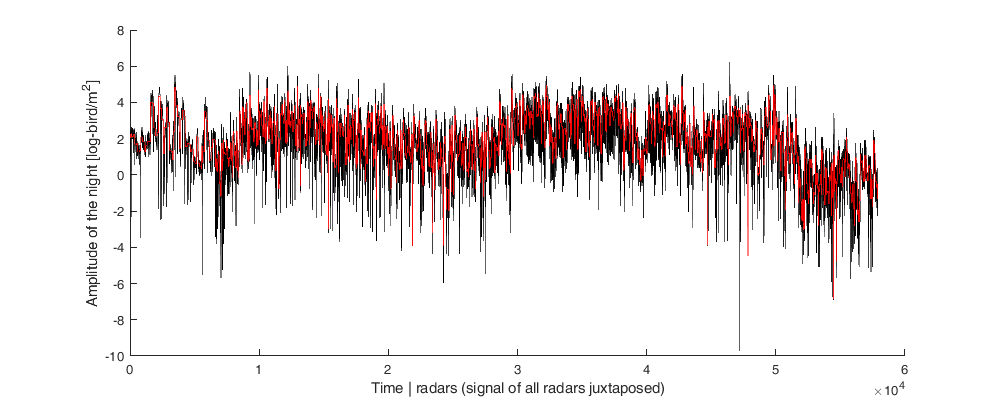

A0=zeros(numel(dc), numel(uniqueDate));
for i=1:numel(A0)
    A0(i)=mean(data.logdens(data.dateradar==i));
end

figure('position',[0 0 1000 400]); hold on; plot(data.logdens,'k'); plot(A0(data.dateradar),'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]')

Intialize the polyfit parameter by the residual of A for all radars. 

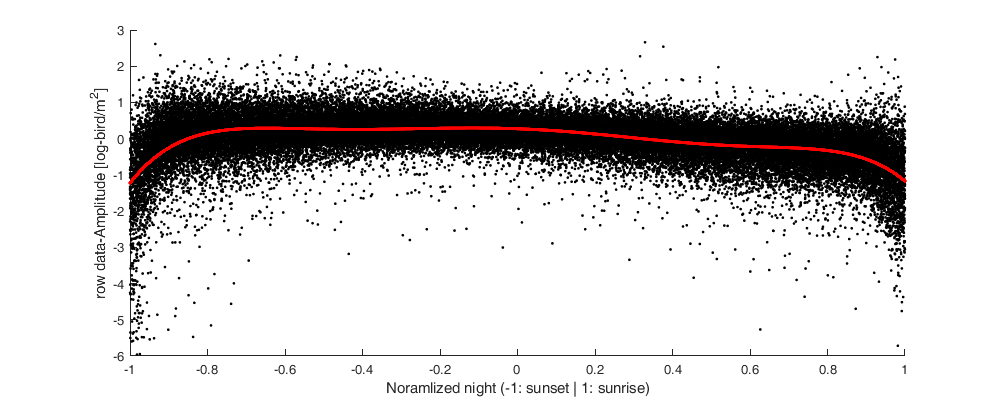

nb_poly=6;
p0 = polyfit(data.scoret,data.logdens-A0(data.dateradar),nb_poly);
figure('position',[0 0 1000 400]); hold on; plot(data.scoret,data.logdens-A0(data.dateradar),'.k'); plot(data.scoret, polyval( p0, data.scoret ),'.r'); ylim([-6 3])
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [log-bird/m^2]')

Performing an optimazation of the amplitude and polyfit parameter combined. 

rmse = @(x) nansum( ( pred(x,size(A0),nb_poly,data.scoret,data.dateradar)  - data.logdens ).^2 );
% options = optimset('PlotFcns',@optimplotfval,'MaxFunEvals',10000);
options = optimset('MaxFunEvals',1000);
x = fminsearch(rmse,[p0(:); A0(:)],options);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 15648.807543 



pf=x(1:nb_poly+1);
Af = reshape(x(nb_poly+2:end),numel(dc),numel(uniqueDate));

Figure

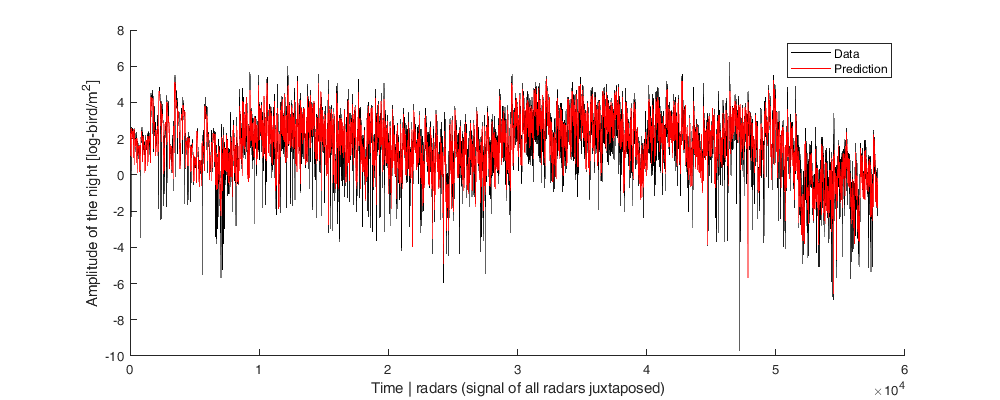

figure('position',[0 0 1000 400]); hold on; plot(data.logdens,'k'); plot(pred([pf(:); Af(:)],size(Af),nb_poly,data.scoret,data.dateradar),'r'); 
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Prediction')

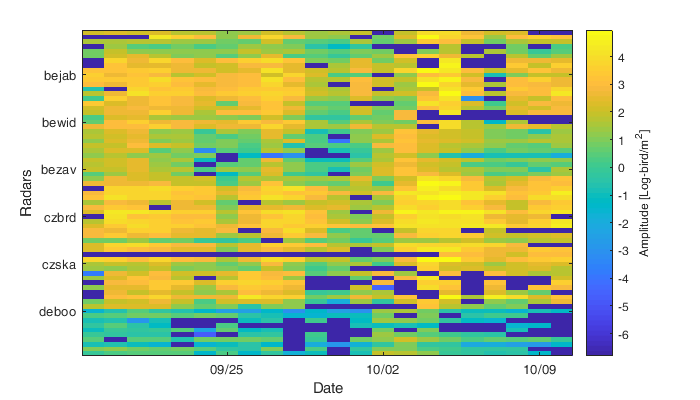

figure('position',[0 0 700 400]); imagesc(uniqueDate,1:numel(dc), Af); datetick('x'); axis tight; c = colorbar; yticklabels({dc.name});
xlabel('Date'); ylabel('Radars');c.Label.String = 'Amplitude [Log-bird/m^2]';

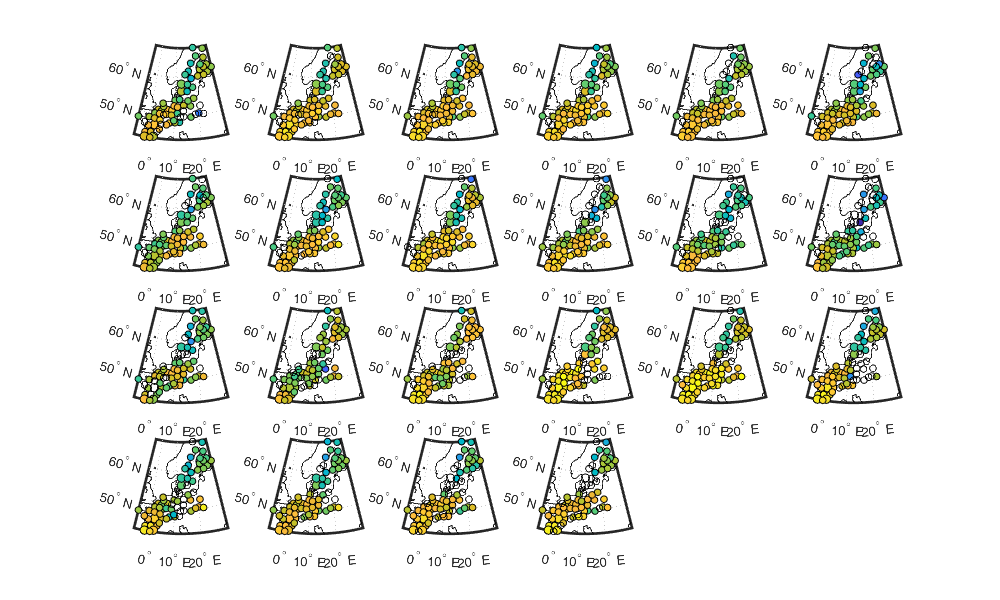

figure('position',[0 0 1000 600]); load coastlines; c_caxis=[min(Af(:)) max(Af(:))];
for i_date = 1:numel(uniqueDate)
    subplot(4,6,i_date); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*1,Af(:,i_date),'filled','MarkerEdgeColor','k');
    caxis(c_caxis);
end

## 3. Kriging Amplitude

## 3.1 Normal Score

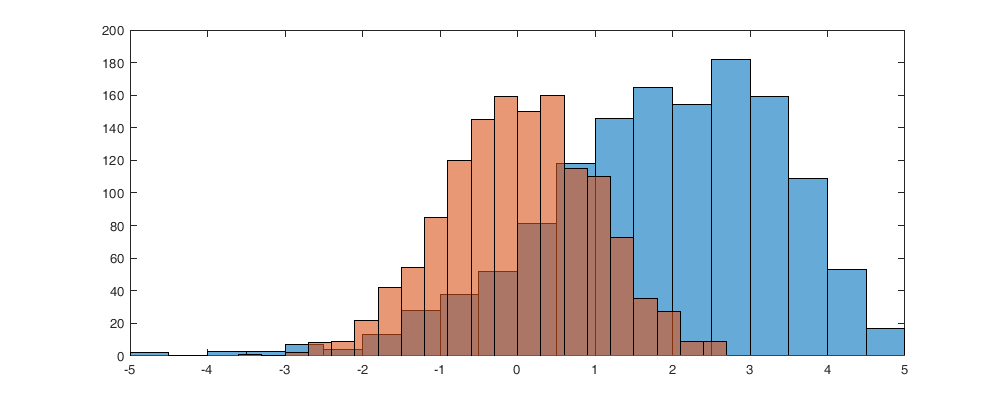

NscoreA = nscore(Af(:));
Af_norm = NscoreA.forward(Af);

figure('position',[0 0 1000 400]); hold on; histogram(Af) ; histogram(Af_norm); box on;xlim([-5 5])

Buliding the distance

Ddist_lat = pdist([repmat([dc.lat]', numel(uniqueDate),1) zeros(numel(dc)*numel(uniqueDate),1)],@lldistkm);
Ddist_lon = pdist([zeros(numel(dc)*numel(uniqueDate),1) repmat([dc.lon]', numel(uniqueDate),1)],@lldistkm);
Dist_km = pdist([repmat([dc.lat]', numel(uniqueDate),1) repmat([dc.lon]', numel(uniqueDate),1)],@lldistkm);
Dtime = pdist(repelem(uniqueDate',numel(dc),1));
Dval = pdist(Af_norm(:));

Dtime_sf=squareform(Dtime);
Dist_km_sf=squareform(Dist_km);

isnanAf=isnan(Af_norm(:));
Dtime_sf=Dtime_sf(~isnanAf,~isnanAf);
Dist_km_sf=Dist_km_sf(~isnanAf,~isnanAf);
val=Af_norm(~isnanAf)-mean(Af_norm(~isnanAf));

## 3.2 Empirical covariogram

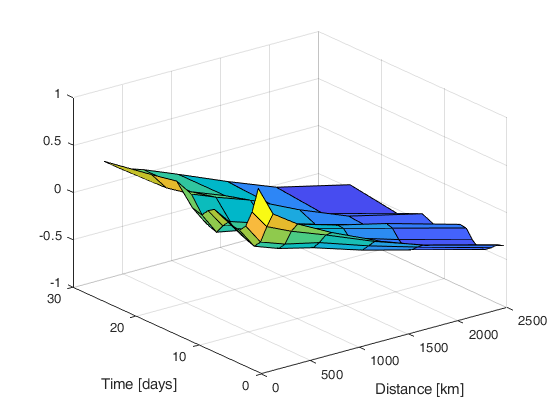

d=[0 1 300 500 1000 1500 2000 3000];
t=[0 1 2 3 4 5 6 7 8 9 10 12 15 20 30]; 
[D,T] = meshgrid(d(1:end-1)+diff(d)/2,t(1:end-1)+diff(t)/2);
c=nan(numel(t)-1,numel(d)-1);
n=nan(numel(t)-1,numel(d)-1);
w=nan(numel(t)-1,numel(d)-1);
for i_t=1:numel(t)-1
    for i_d=1:numel(d)-1
        id = Dtime_sf>=t(i_t) & Dtime_sf<t(i_t+1) & Dist_km_sf>=d(i_d) & Dist_km_sf<d(i_d+1);
        [id1, id2]=find(id);
        c(i_t,i_d) = mean( val(id1) .* val(id2));
        %n(i_t,i_d) = sum(id(:));
        %w(i_t,i_d) = sum(cov_emp_weight(id(id_timedistmax)));
        %v(i_t,i_d) = nanmean((Dval(Dtime>=t(i_t) & Dtime<t(i_t+1) & Dist_km>=d(i_d) & Dist_km<d(i_d+1)).^2)./2);
    end
end
figure;surf(D,T,c); xlabel('Distance [km]'); ylabel('Time [days]')


pp=nan(max(Dtime)+1,10);
for i_t=1:max(Dtime)+1
    id = Dtime_sf==i_t-1;
    [id1, id2]=find(id);
    pp(i_t,:)=polyfit(Dist_km_sf(id), val(id1) .* val(id2),size(pp,2)-1);
end

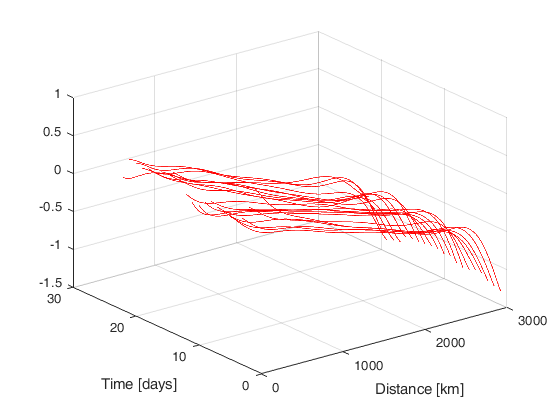


figure; hold on; grid on
for i_t=1:max(Dtime)+1
    plot3(0:3000,i_t*ones(3001,1),polyval(pp(i_t,:),0:3000),'r')
end
xlabel('Distance [km]'); ylabel('Time [days]'); view(3)

## 3.3 Variogram fitting

The variogram fitted is composed of a nugget and Gneiting model. The data are filtered by a maximum distance and time and reduce the computational cost and overfitting long-distance/time lag. First a gloabl optimzer is used (multi-start) and then a local optimizer refine the result

dist_max=1200; time_max=10;
id_timedistmax = find(Dist_km_sf<dist_max & Dtime_sf<time_max & ~(Dist_km_sf==0 & Dtime_sf==0));

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
% Gneiting_fit = @(x) x(1).* (Dist_km_sf(id_timedistmax)==0&Dtime_sf(id_timedistmax)==0) + x(2).*Gneiting(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),x(3),x(4),x(5),x(6),x(7));
Gneiting_fit = @(x) x(1).*Gneiting(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),x(2),x(3),x(4),x(5),x(6));

cova0=[.7 500 10 0 .5 .5];
cova_min=[0 0.0001 0 0 0 0 ]';
cova_max=[nancov(val) 3000 10 1 1 1]';

cov_emp = bsxfun(@times, val', val);

Weightings method

%[f,xi]=ksdensity([Dtime_sf(id_timedistmax) Dist_km_sf(id_timedistmax)]);
%cov_emp_weight =1./griddata(xi(:,1),xi(:,2),f,Dtime_sf(id_timedistmax), Dist_km_sf(id_timedistmax));

%cov_emp_weight = 1./( sqrt((Dtime_sf(id_timedistmax)./time_max).^2 + (Dist_km_sf(id_timedistmax)./dist_max).^2 ));

cov_emp_weight=nan(size(Dist_km_sf));
for i_t=1:max(Dtime)+1
    id = Dtime_sf==i_t-1;
    cov_emp_weight(id) = polyval(pp(i_t,:),Dist_km_sf(id));
end
cov_emp_weight = cov_emp_weight(id_timedistmax);
cov_emp_weight(cov_emp_weight<0)=0;

% scatter3(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),cov_emp_weight./nansum(cov_emp_weight),'.r')
 rmse = @(cova) sum( ( Gneiting_fit(cova)  -  cov_emp(id_timedistmax) ).^2 .* cov_emp_weight./sum(cov_emp_weight) );

% scatter3(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),Gneiting_fit(cova)./sum(Gneiting_fit(cova)),'.g')
% rmse = @(cova) sum( ( Gneiting_fit(cova)  -  cov_emp(id_timedistmax) ).^2 .* Gneiting_fit(cova)./sum(Gneiting_fit(cova)) );

Minsearch

cova = fmincon(rmse,cova0,[],[],[],[],cova_min,cova_max,[]);%,optimset('PlotFcn',@optimplotfval))


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

cova = [nancov(val)-cova(1) cova];
sprintf('%.2f ',cova)

ans = '0.25 0.70 409.26 8.83 0.00 1.00 1.00 '

Figure

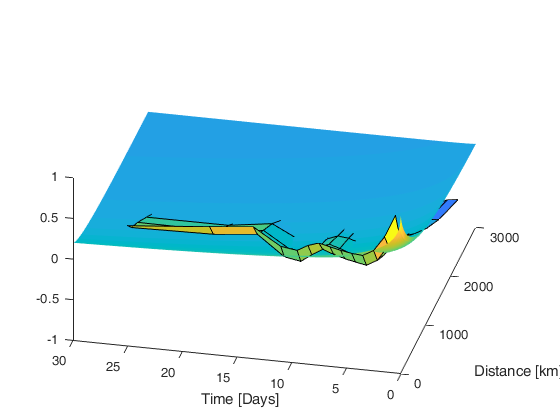

[D2,T2] = meshgrid(d(1):1:d(end),t(1):0.1:t(end));
COV=cova(2).*Gneiting(D2(:), T2(:), cova(3), cova(4), cova(5), cova(6), cova(7));
COV=reshape(COV,size(D2,1),size(D2,2));
COV(1)=COV(1)+cova(1);
figure; hold on;
s=surf(D2,T2,COV);
surf(D,T,c);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 3.4 Estimate Amplitude with kriging

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
cova = [0.00 0.94 579.72 2.99 0.28 0.38 0.00];

z=Af_norm(~isnan(Af_norm(:)));

Ca = cova(2).*Gneiting(squareform(Dist_km),squareform(Dtime), cova(3), cova(4), cova(5), cova(6), cova(7));
Ca = Ca + diag(repmat(cova(1),size(Ca,1),1));

Ca(isnan(Af_norm(:)),:)=[];
Ca(:,isnan(Af_norm(:)))=[];
[~,R] = meshgrid(uniqueDate,1:numel(dc));
R=R(~isnan(Af_norm(:)));
z_est=nan(size(z));
z_sigma=nan(size(z));

for i_d=1:numel(dc)
    rid = find(R==i_d);
    Caa = Ca;
    Caa(rid,:)=[];
    Caa(:,rid)=[];
    Cab = Ca(:,rid);
    Cab(rid,:)=[];
    for i_rid=1:numel(rid)
        lambda = Caa  \  Cab(:,i_rid);
        z_est(rid(i_rid)) =  lambda' * z(R~=i_d);
        z_sigma(rid(i_rid)) = cova(1) + cova(2) - lambda' * Cab(:,i_rid);
    end
end



Figure;

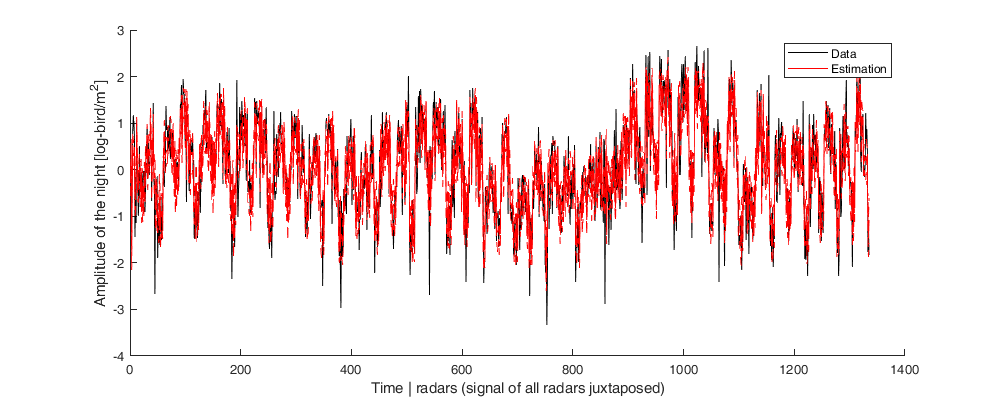

figure('position',[0 0 1000 400]); hold on;
plot(z,'k');
plot(z_est,'r')
plot(z_est-z_sigma,'--r')
plot(z_est+z_sigma,'--r')
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Estimation')

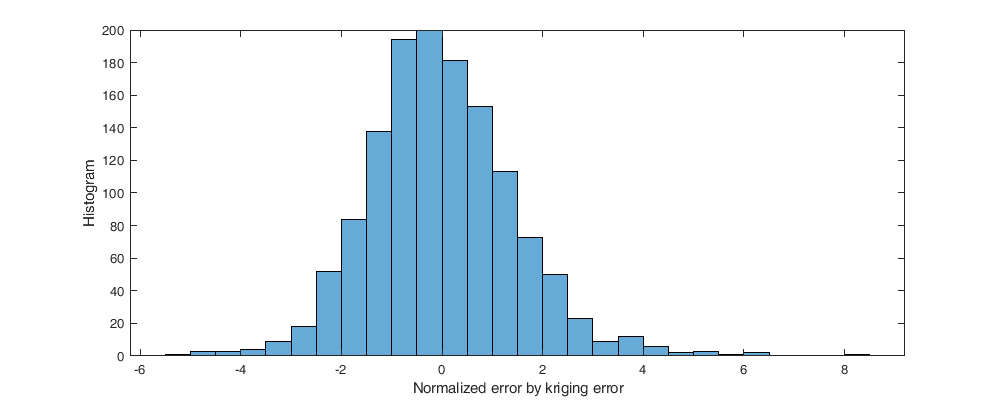

figure('position',[0 0 1000 400]); histogram((z_est-z)./z_sigma)
ylabel('Histogram'); xlabel('Normalized error by kriging error')

## 3.5 Back-transform

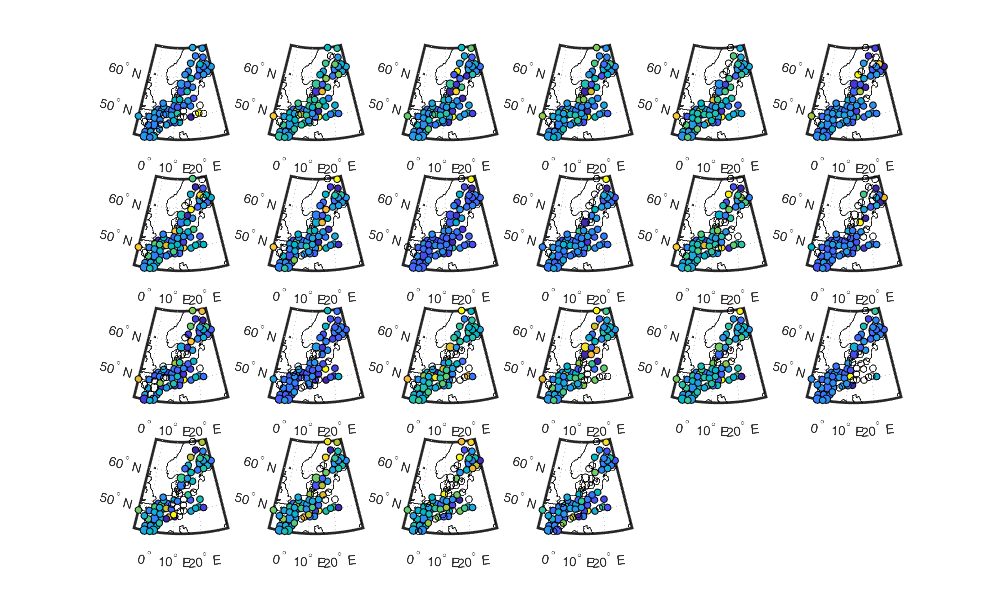

Aest_norm = Af;
Aest_norm(~isnan(Af(:))) = z_est;
Asigma_norm = Af;
Asigma_norm(~isnan(Af(:))) = z_sigma;

Aest = NscoreA.inverse(Aest_norm);
for i=-3:3
    Aest_err(:,:,i+4) = NscoreA.inverse(Aest_norm+Asigma_norm.*i);
end

figure('position',[0 0 1000 600]); load coastlines;
for i_date = 1:numel(uniqueDate)
    subplot(4,6,i_date); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*1,Aest(:,i_date)-Af(:,i_date),'filled','MarkerEdgeColor','k'); 
     % colorbar;
end

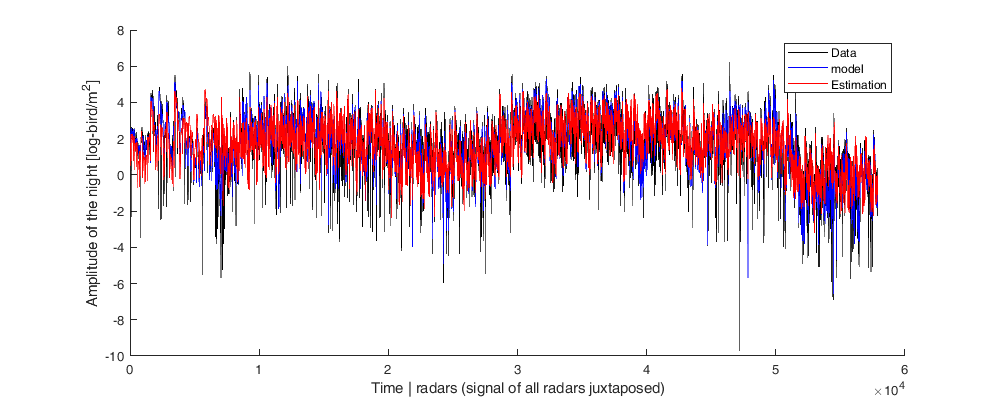

figure('position',[0 0 1000 400]); hold on; 
plot(data.logdens,'k'); 
plot(pred([pf(:); Af(:)],size(Af),nb_poly,data.scoret,data.dateradar),'b');
plot(pred([pf(:); Aest(:)],size(Aest),nb_poly,data.scoret,data.dateradar),'r');

xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','model','Estimation')

## 3.6 Co-Kriging Amplitude with wind

Get the wind

Wu=zeros(numel(dc), numel(uniqueDate));
Wv=zeros(numel(dc), numel(uniqueDate));
for i=1:numel(Wu)
    Wu(i)=mean(data.wind(data.dateradar==i,1));
    Wv(i)=mean(data.wind(data.dateradar==i,9));
end

Normalized the wind

NscoreWu = nscore(Wu(:));
Wu_norm = NscoreWu.forward(Wu);
NscoreWv = nscore(Wv(:));
Wv_norm = NscoreWv.forward(Wv);

Compute the empirical covariogram

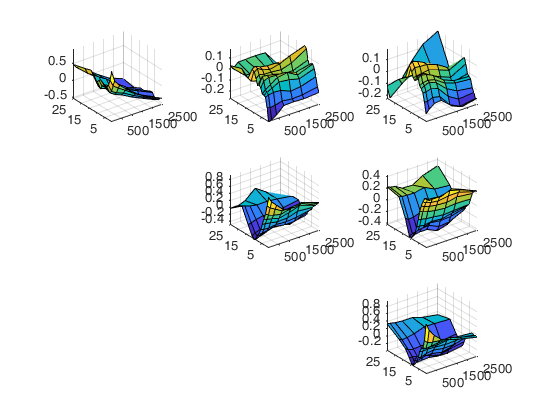

Dtime_sf=squareform(Dtime);
Dist_km_sf=squareform(Dist_km);

isnanAll=isnan(Af_norm(:));
Dtime_sf=Dtime_sf(~isnanAll,~isnanAll);
Dist_km_sf=Dist_km_sf(~isnanAll,~isnanAll);
val = [Af_norm(~isnanAll)-nanmean(Af_norm(:)) Wu_norm(~isnanAll)-nanmean(Wu_norm(:)) Wv_norm(~isnanAll)-nanmean(Wv_norm(:))]';


c = nan(numel(t)-1,numel(d)-1,3,3);
for i_t=1:numel(t)-1
    for i_d=1:numel(d)-1
        id = Dtime_sf>=t(i_t) & Dtime_sf<t(i_t+1) & Dist_km_sf>=d(i_d) & Dist_km_sf<d(i_d+1);
        [id1, id2]=find(id);
        for i1=1:3
            for i2=i1:3
                c(i_t,i_d,i1,i2) = nanmean( val(i1,id1) .* val(i2,id2) );
            end
        end
    end
end

figure;
for i1=1:3
    for i2=i1:3
        subplot(3,3,(i1-1)*3+i2);
         surf(D,T,c(:,:,i1,i2)); axis tight;
         %xlabel('Distance [km]'); ylabel('Time [days]')
    end
end

Calibrate the (cross-)covariance 

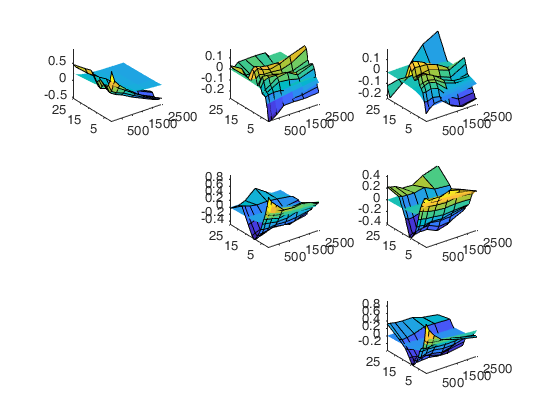

dist_max=1200; time_max=10;
id_timedistmax = find(Dist_km_sf<dist_max & Dtime_sf<time_max);
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(x) x(2).*Gneiting(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),x(3),x(4),x(5),x(6),x(7));

covac0 = reshape([0.231 0.712 675.334 1.776 0.859 0.943 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.027 -0.242 2000.009 1.090 1.000 0.992 0.996 0.051 0.893 3213.359 1.887 1.000 0.228 0.002 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.019 -0.140 2747.358 1.005 1.000 0.999 0.996 -0.009 0.437 3591.680 2.430 1.000 1.000 0.990 0.322 0.632 3997.459 1.906 0.882 0.304 0.998],7,3,3);
covac_min=[-1 -1 0.0001 0 0 0 0]';
covac_max=[1 1 4000 20 1 1 1]';
covac_var = cov(val');

for i1=1:3
    for i2=i1:3
        pp=nan(max(Dtime)+1,10);
        cov_emp_weight=nan(size(Dist_km_sf));
        for i_t=1:max(Dtime)+1
            id = Dtime_sf==i_t-1;
            [id1, id2]=find(id);
            pp(i_t,:)=polyfit(Dist_km_sf(id), val(i1,id1)' .* val(i2,id2)', size(pp,2)-1);
            cov_emp_weight(id) = polyval(pp(i_t,:),Dist_km_sf(id));
        end
        cov_emp_weight = cov_emp_weight(id_timedistmax);
        cov_emp_weight(cov_emp_weight.*covac_var(i1,i2)<0)=0;
        
        % figure; scatter3(Dist_km_sf(id_timedistmax),Dtime_sf(id_timedistmax),cov_emp_weight./nansum(cov_emp_weight),'.r')
        
        cov_emp = bsxfun(@times, val(i1,:)', val(i2,:));
        rmse = @(cova) sum( ( Gneiting_fit(cova)  -  cov_emp(id_timedistmax) ).^2 .* cov_emp_weight./sum(cov_emp_weight) );

        covac(:,i1,i2) = fmincon(rmse,covac0(:,i1,i2),[],[],[],[],covac_min,covac_max,[]);%,optimset('PlotFcn',@optimplotfval))
        covac(1,i1,i2) = covac_var(i1,i2)-covac(2,i1,i2);

    end
end

% sprintf('%.3f ',covac)
% covac = reshape([0.231 0.712 675.334 1.776 0.859 0.943 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.027 -0.242 2000.009 1.090 1.000 0.992 0.996 0.051 0.893 3213.359 1.887 1.000 0.228 0.002 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.019 -0.140 2747.358 1.005 1.000 0.999 0.996 -0.009 0.437 3591.680 2.430 1.000 1.000 0.990 0.322 0.632 3997.459 1.906 0.882 0.304 0.998],7,3,3);
% covac = reshape([-0.015 0.958 569.909 2.916 0.278 0.375 0.001 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.003 -0.266 2000.009 1.333 0.999 0.543 0.996 0.054 0.890 3213.359 1.968 1.000 0.240 0.005 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.032 -0.128 2747.358 2.391 0.696 0.999 0.993 0.014 0.414 3591.680 2.779 1.000 0.999 0.968 0.109 0.845 3997.195 1.502 0.687 0.188 0.998],7,3,3);
figure(4);clf;
for i1=1:3
    for i2=i1:3
        subplot(3,3,(i1-1)*3+i2); hold on;
        surf(D,T,c(:,:,i1,i2)); %xlabel('Distance [km]'); ylabel('Time [days]')
        COV=covac(2,i1,i2).*Gneiting(D(:), T(:), covac(3,i1,i2), covac(4,i1,i2), covac(5,i1,i2), covac(6,i1,i2), covac(7,i1,i2));
        COV=reshape(COV,size(D,1),size(D,2));
        COV(1)=COV(1)+covac(1,i1,i2);
        s=surf(D,T,COV); s.EdgeColor='none'; view(3); axis tight;
    end
end

Co-Kriging

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
covac = reshape([-0.015 0.958 569.909 2.916 0.278 0.375 0.001 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.003 -0.266 2000.009 1.333 0.999 0.543 0.996 0.054 0.890 3213.359 1.968 1.000 0.240 0.005 0.000 0.000 0.000 0.000 0.000 0.000 0.000 -0.032 -0.128 2747.358 2.391 0.696 0.999 0.993 0.014 0.414 3591.680 2.779 1.000 0.999 0.968 0.109 0.845 3997.195 1.502 0.687 0.188 0.998],7,3,3);
n = size(Dist_km_sf,1);

C = nan(n*3);
for i1=1:3
    for i2=i1:3
        tmpo = covac(2,i1,i2).*Gneiting(Dist_km_sf, Dtime_sf, covac(3,i1,i2), covac(4,i1,i2), covac(5,i1,i2), covac(6,i1,i2), covac(7,i1,i2));
        C((i1-1)*n+(1:n),(i2-1)*n+(1:n)) = tmpo + diag(repmat(covac(1,i1,i2),n,1));
    end
end
C=triu(C)+triu(C,1)';




z=Af_norm(~isnanAll);
y1=Wu_norm(~isnanAll);
y2=Wv_norm(~isnanAll);


[~,R] = meshgrid(uniqueDate,1:numel(dc));
RAf=R(~isnanAll);
zCo_est=nan(size(z));
zCo_sigma=nan(size(z));


for i_d=1:numel(dc)
    rid = find(RAf==i_d);
    Caa = C;
    Caa(rid,:)=[];
    Caa(:,rid)=[];
    Cab = C(:,rid);
    Cab(rid,:)=[];
    
    id = ones(size(Cab,1),1);
    id(sum(RAf~=i_d)+(1:numel(y1)))=2;
    id(sum(RAf~=i_d)+numel(y1)+(1:numel(y2)))=3;
    
    for i_rid=1:numel(rid)
       
        idCab = abs(Cab(:,i_rid))>.05;
        
        lambda = zeros(size(Cab,1),1);
        lambda(idCab) = Caa(idCab,idCab) \  Cab(idCab,i_rid);
        
        while sum(abs(lambda))>10
            [~,i] = max(abs(lambda));
            ii=[ii;i];
            idCab(i) = 0;
            lambda(i)=0;
            lambda(idCab) = Caa(idCab,idCab) \  Cab(idCab,i_rid);
            disp(['sum(lambda)>10: i=' num2str(i) ', new sum(lambda)=' num2str(sum(abs(lambda)))] )
        end
        
        zCo_est(rid(i_rid)) =  lambda' * [z(RAf~=i_d); y1 ; y2];
        zCo_sigma(rid(i_rid)) = isnanAll(1,1,1) + covac(2,1,1) - lambda(idCab)' * Cab(idCab,i_rid);
        

        assert(abs(zCo_est(rid(i_rid)))<4,'Error of kriging')
        
%         figure(4);clf; 
%         a=lambda; 
%         a=idCab;
%         %a=Cab(:,i_rid);
%         c_axis=[min(double(a)) max(a)];
%         subplot(1,3,1); hold on;view([ -110.4000   46.0000]); caxis(c_axis)
%         scatter3(dc(RAf(rid(i_rid))).lon,dc(RAf(rid(i_rid))).lat,TAf(rid(i_rid)),'r','filled')
%         scatter3([dc(RAf(RAf~=i_d)).lon],[dc(RAf(RAf~=i_d)).lat],TAf(RAf~=i_d),[],a(id==1),'filled')
%         subplot(1,3,2); hold on;view([ -110.4000   46.0000]); caxis(c_axis)
%         scatter3(dc(RAf(rid(i_rid))).lon,dc(RAf(rid(i_rid))).lat,TAf(rid(i_rid)),'r','filled')
%         scatter3([dc(RAf).lon],[dc(RAf).lat],TAf,[],a(id==2),'filled')
%         subplot(1,3,3); hold on; view([ -110.4000   46.0000]); caxis(c_axis)
%         scatter3(dc(RAf(rid(i_rid))).lon,dc(RAf(rid(i_rid))).lat,TAf(rid(i_rid)),'r','filled')
%         scatter3([dc(RAf).lon],[dc(RAf).lat],TAf,[],a(id==3),'filled')     
        
    end
end

Back-transform and Figure

figure('position',[0 0 1000 400]); hold on;
plot(z,'k');
plot(z_est,'r')
plot(z_est-z_sigma,'--r')
plot(z_est+z_sigma,'--r')
plot(zCo_est,'b')
plot(zCo_est-z_sigma,'--b')
plot(zCo_est+z_sigma,'--b')
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Estimation')

Compare the normalized error of kriging with co-kriging with the kriging in 3.5. The normalized variance is much smaller indicating a better estimation with the addition of the covariable

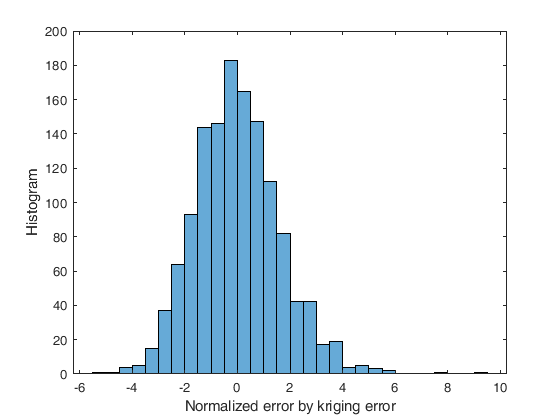

figure('position',[0 0 1000 400]); hold on;
histogram((z_est-z)./z_sigma)
histogram((zCo_est-z)./zCo_sigma)
ylabel('Histogram'); xlabel('Normalized error by kriging error')

sqrt(nanmean((z_est-z).^2))

sqrt(nanmean((zCo_est-z).^2))

Back-transform data

ACoest_norm = Af;
ACoest_norm(~isnan(Af(:))) = z_est;
ACo_sigma_norm = Af;
ACo_sigma_norm(~isnan(Af(:))) = z_sigma;

ACoest = NscoreA.inverse(ACoest_norm);
for i=-3:3
    ACoest_err(:,:,i+4) = NscoreA.inverse(ACoest_norm+ACo_sigma_norm.*i);
end

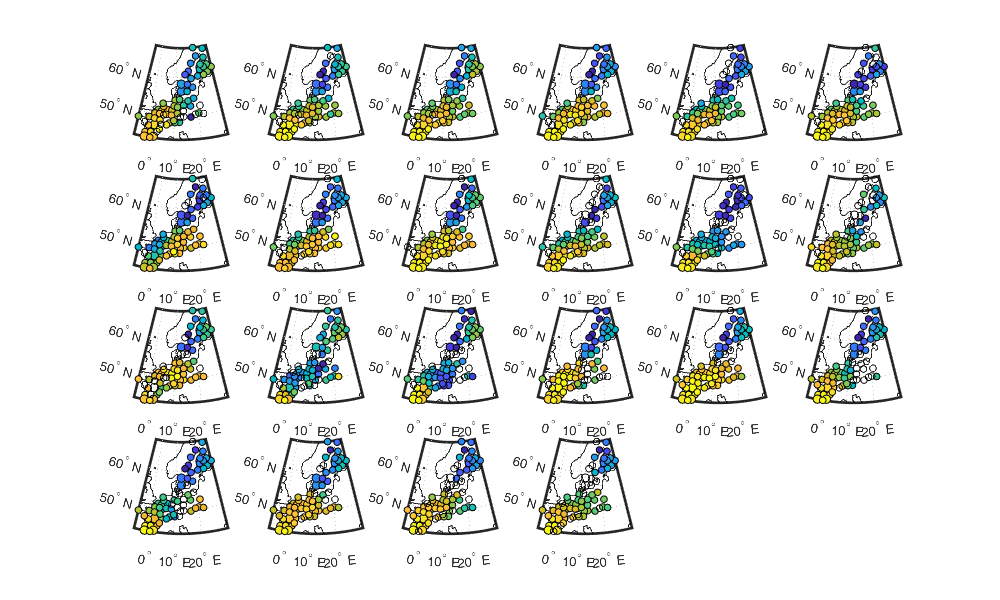

figure('position',[0 0 1000 600]); load coastlines;
for i_date = 1:numel(uniqueDate)
    subplot(4,6,i_date); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*1,ACoest(:,i_date),'filled','MarkerEdgeColor','k'); 
     % colorbar;
end

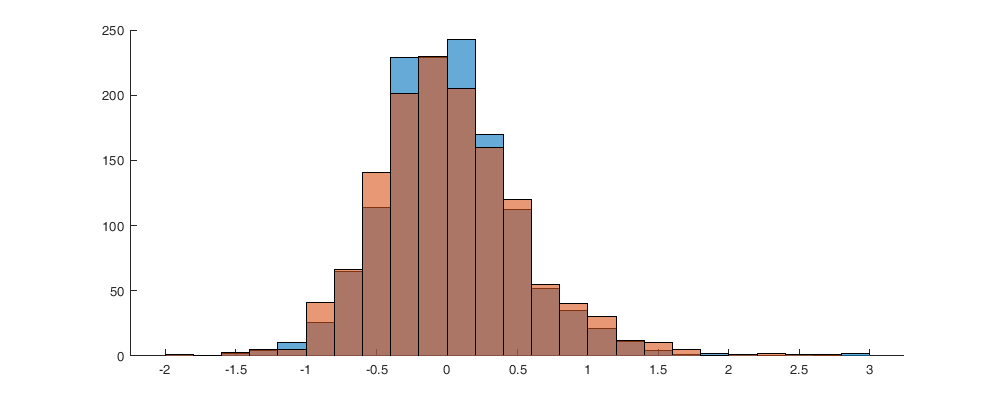

figure('position',[0 0 1000 400]); hold on;
histogram(NscoreA.forward(Aest(:))-Af_norm(:));
histogram(NscoreA.forward(ACoest(:))-Af_norm(:));


sqrt(nansum((NscoreA.forward(ACoest(:))-Af_norm(:)).^2))

ans = 19.2383

ans = 17.8055

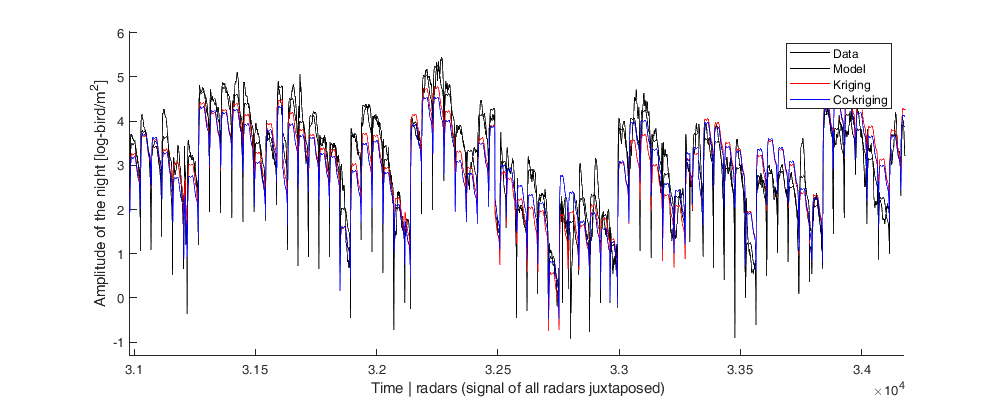


figure('position',[0 0 1000 400]); hold on; 
plot(data.logdens,'k'); 
plot(pred([pf(:); Af(:)],size(Af),nb_poly,data.scoret,data.dateradar),'k');
plot(pred([pf(:); Aest(:)],size(Aest),nb_poly,data.scoret,data.dateradar),'r');
plot(pred([pf(:); ACoest(:)],size(ACoest),nb_poly,data.scoret,data.dateradar),'b');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Model','Kriging','Co-kriging')

## 4. Residus

data.resrow = data.logdens-pred([pf(:); Af(:)],size(A0),nb_poly,data.scoret,data.dateradar);

## 4.1 Normalization residu

Normalized the noise according to the night

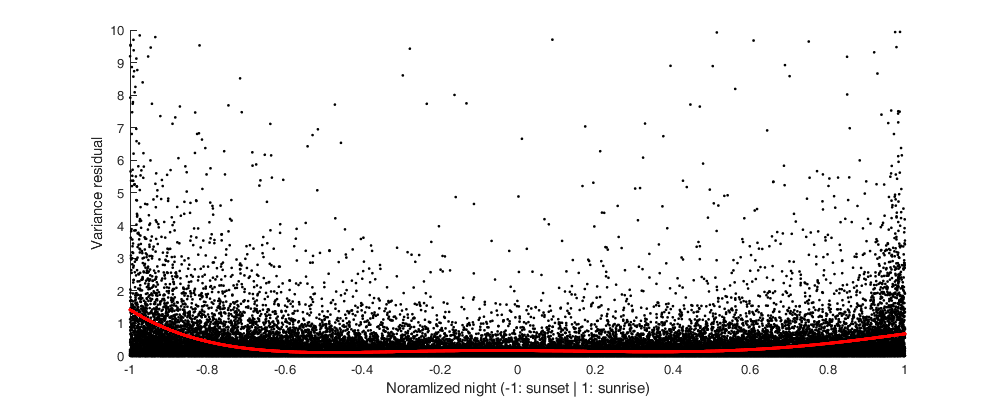

pr = polyfit(data.scoret,data.resrow.^2,5);
data.res = data.resrow./sqrt(polyval(pr,data.scoret));

figure('position',[0 0 1000 400]); hold on;
plot(data.scoret,data.resrow.^2,'.k'); plot(data.scoret,polyval(pr,data.scoret),'.r'); ylim([0 10]); 
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('Variance residual')

Normalized the residu

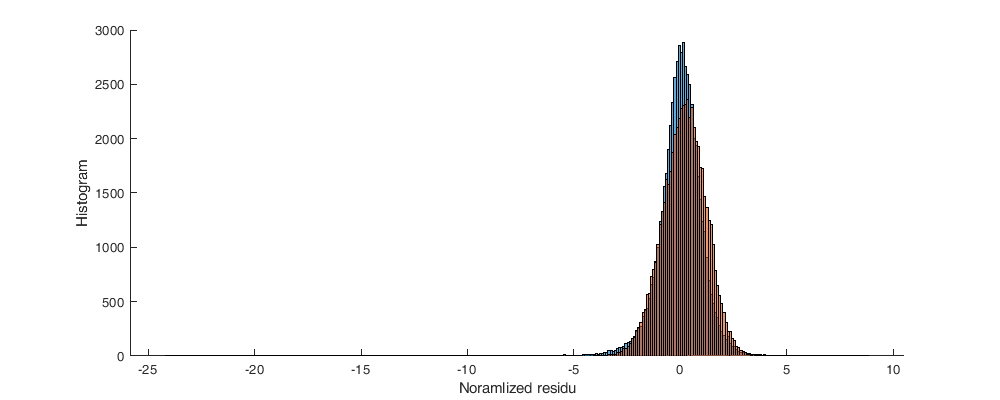

NscoreRes = nscore(data.res);
data.resnorm = NscoreRes.forward(data.res);

figure('position',[0 0 1000 400]); hold on; histogram(data.res) ; histogram(data.resnorm)
xlabel('Noramlized residu'); ylabel('Histogram')

Plot nomalized residu

Plot spatio-temporal residual. You can change resnorm by resrow or res to see the variation

h=figure(2); load coastlines; 
t=start_date+1:1/24/4:end_date-1;
F2(numel(t)-1) = struct('cdata',[],'colormap',[]); 
for i_t = 402:numel(t)-1
    clf; worldmap('Europe');
    plotm(coastlat, coastlon,'k')
    id = data.time>datenum(t(i_t)) & data.time<=datenum(t(i_t+1));
    scatterm(data.lat(id),data.lon(id),100,data.resnorm(id),'filled','MarkerEdgeColor','k');
    title(datestr(t(i_t))); caxis([-2 2]); drawnow;
    F2(i_date) = getframe(h);
end
v=VideoWriter('res.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);


## 4.2 Built matrix of distance

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

time_max=0.45;

Ddist_dc_lat = squareform(pdist([[dc.lat]' zeros(numel(dc),1)],@lldistkm));
Ddist_dc_lon = squareform(pdist([zeros(numel(dc),1) [dc.lon]'],@lldistkm));
Dist_dc_km = squareform(pdist([[dc.lat]' [dc.lon]'],@lldistkm));

nid1=nan(height(data),1);
parfor i_data=1:height(data)
    nid1(i_data)=sum(abs(data.time(i_data)-data.time)<=time_max);
end

n_neigh = max(nid1);
Ddist_lat = nan(n_neigh, height(data));
Ddist_lon = nan(n_neigh, height(data));
Ddist_km = nan(n_neigh, height(data));
Dtime = nan(n_neigh, height(data));
Dval = nan(n_neigh, height(data));
Dvalabs = nan(n_neigh, height(data));
Did = nan(n_neigh, height(data));
Dnid = nan(n_neigh, height(data));

for i_data=1:height(data)
    c=abs(data.time(i_data)-data.time);
    id1=find(c<=time_max);

    Ddist_lat(:,i_data) = [Ddist_dc_lat(data.i_d(i_data),data.i_d(id1)) nan(1,n_neigh-nid1(i_data))];
    Ddist_lon(:,i_data) = [Ddist_dc_lon(data.i_d(i_data),data.i_d(id1)) nan(1,n_neigh-nid1(i_data))];
    Ddist_km(:,i_data) = [Ddist_dc_km(data.i_d(i_data),data.i_d(id1)) nan(1,n_neigh-nid1(i_data))];
    Dtime(:,i_data) = [c(id1) ; nan(n_neigh-nid1(i_data),1)];
    Dval(:,i_data) = [data.resnorm(i_data)-data.resnorm(id1) ; nan(n_neigh-nid1(i_data),1)];
    Dvalabs(:,i_data) = [abs(data.resnorm(i_data))-abs(data.resnorm(id1)) ; nan(n_neigh-nid1(i_data),1)];
    Did(:,i_data) = [i_data*ones(numel(id1),1) ; nan(n_neigh-nid1(i_data),1)];
    Dnid(:,i_data) = [id1 ; nan(n_neigh-nid1(i_data),1)];
end

Ddist_lat=Ddist_lat(~isnan(Ddist_lat));
Ddist_lon=Ddist_lon(~isnan(Ddist_lon));
Ddist_km=Ddist_km(~isnan(Ddist_km));
Dtime=Dtime(~isnan(Dtime));
Dval=Dval(~isnan(Dval));
Dvalabs=Dvalabs(~isnan(Dvalabs));
Did=Did(~isnan(Did));
Dnid=Dnid(~isnan(Dnid));

## 4.3 Empirical Variogram

x=[0 50 100 150 200 250 300 600 1000 1500 2000 3000];
y=[0 .01 .02 .05 .07 .1 .15 .2 .25 .3 .35 .4 .45]; 
[X,Y]=meshgrid(x(1:end-1)+diff(x)/2,y(1:end-1)+diff(y)/2);
M=nan(size(X')); Mabs=nan(size(X')); N=nan(size(X'));
for i_x=1:numel(x)-1
    id1 = find(Dist_km>=x(i_x) & Dist_km<x(i_x+1));
    for i_y=1:numel(y)-1
        id2 = id1(Dtime(id1)>=y(i_y) & Dtime(id1)<y(i_y+1));
        M(i_x,i_y)=mean(Dval(id2).^2)./2;
        Mabs(i_x,i_y)=mean(Dvalabs(id2).^2)./2;
        N(i_x,i_y)=numel(id2);
    end
end

Figure

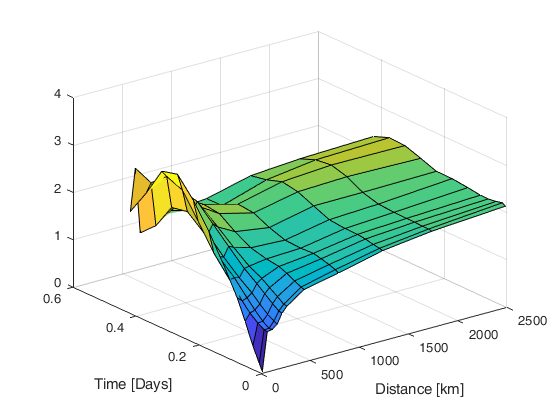

figure; surf(X,Y,M');  xlabel('Distance [km]'); ylabel('Time [Days]');

The empirical variogram of the residu shows a very intersting effect.

[...] 

The empirical variogram of the absolute value of the residu confirms our explanation with the lowest variance.

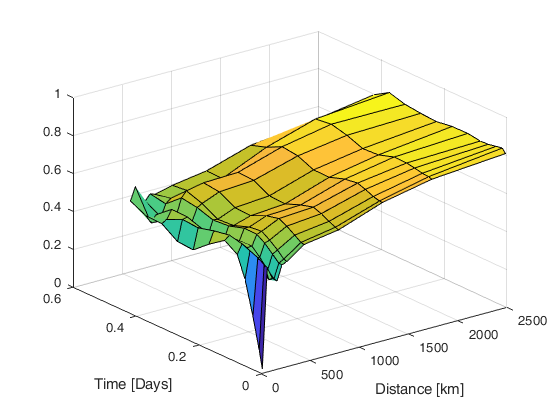

figure; surf(X,Y,Mabs'); xlabel('Distance [km]'); ylabel('Time [Days]');

Spatial Anisotropie

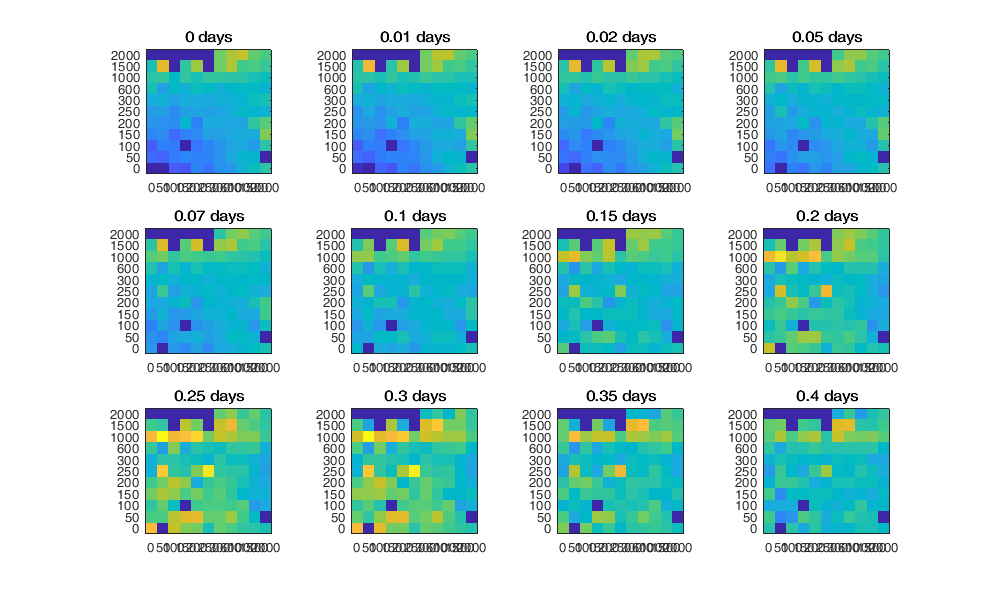

M2=nan(numel(x)-1,numel(x)-1,numel(y)-1);
for i_y=1:numel(y)-1
    id1 = find(Dtime>=y(i_y) & Dtime<y(i_y+1));
    for i_x1=1:numel(x)-1
        id2 = id1(Ddist_lat(id1)>=x(i_x1) & Ddist_lat(id1)<x(i_x1+1));
        for i_x2=1:numel(x)-1
            id3 = id2(Ddist_lon(id2)>=x(i_x2) & Ddist_lon(id2)<x(i_x2+1));
            M2(i_x1,i_x2,i_y)=mean(Dval(id3).^2)./2;
        end
    end
end

figure('position',[0 0 1000 600]); 
for i_y=1:numel(y)-1
    subplot(3,4,i_y);imagesc(M2(:,:,i_y)); 
    caxis([0 max(M2(:))]);set(gca,'YDir','normal'); axis equal tight; title([num2str(y(i_y)) ' days']); 
    yticks(1:numel(x)); yticklabels(x)
    xticks(1:numel(x)); xticklabels(x)
end

## 4.4 Calibrate covariance 

We start by limiting the data to those with a lag temporal of less than half of the night to avoid the night compensation effect

night_length =mean(([dc.sunset]-[dc.sunrise]));
time_max=hours(night_length)/24/2;
id_timemax = find(Dtime<=time_max & ~(Dist_km==0 & Dtime==0));

Then define the covariance

% With Anisotropie
% cx =@(azimuth,range) [cos(azimuth/180*pi),-sin(azimuth/180*pi);sin(azimuth/180*pi),cos(azimuth/180*pi)]/diag(fliplr(range));
% dist_fx = @(dist,azimuth,range_dist) sqrt(sum((dist*cx(azimuth,range_dist)).^2,2));
% Gneiting = @(dist,time,range_dist,azimuth,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-dist_fx(dist,azimuth,range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
% Gneiting_fit = @(x,id) x(1)+x(2)-x(2).*Gneiting([Ddist_lat(id) Ddist_lon(id)],Dtime(id),[x(3) x(4)],x(5),x(6),x(7),x(8),x(9));
% 
% c0 = mean(Dval(Ddist_lat>0&Ddist_lon>0&Dtime>0&Ddist_lat<100&Ddist_lon<100&Dtime<=1/24/6).^2);
% c1 = mean(Dval(Ddist_lat>1700&Ddist_lon>1700&Dtime>0.2).^2)-c0;
% cov0=[c0 c1 500 2000 80 0.2 .9 .5 1];
% cov_min=[0 0 0.001 0.0001 30 0 0 0 0]';
% cov_max=[2 2 3000 3000 120 .5 1 1 1]';

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(x,id) x(1)+x(2)-x(2).*Gneiting(Dist_km(id_timemax(id)),Dtime(id_timemax(id)),x(3),x(4),x(5),x(6),x(7));

Perform a global optimal search on a limited number of observation and fast convergence with 30 different starting point. The covariance parameters are, in order

- `c0`, nugget 

- `c1`, variance

- `range_x`, range in x

- `range_y`, range in y

- `azimuth`, anisotropie angle

- `range_t`, range in time

- `delta`, spatial shape

- `gamma`, temporal shape

- `beta`, spatio-temporale link

c0 = mean(Dval(Dist_km(id_timemax)>0&Dtime(id_timemax)>0&Dist_km(id_timemax)<100&Dtime(id_timemax)<=1/24/4).^2./2);
c1 = mean(Dval(Dist_km(id_timemax)>1700&Dtime(id_timemax)>0.2).^2./2)-c0;
cov0=[c0 c1 2000 0.2 .9 .5 .5];
cov_min=[0 0 0.0001 0 0 0 0]';
cov_max=[2 2 3000 .5 1 1 1]';

id=randi(numel(Dval),500000,1);
rmse = @(x) nanmean( ( Gneiting_fit(x,id)  -  Dval(id).^2./2).^2 );

options = optimoptions('fmincon','PlotFcns',@optimplotfval,'Algorithm','interior-point','MaxFunctionEvaluations',100000,'OptimalityTolerance',1e-6);
pb = createOptimProblem('fmincon','objective',rmse,'lb',cov_min,'ub',cov_max,'x0',cov0,'options',options);
ms = MultiStart('Display','iter','PlotFcn',@gsplotbestf);
[~,~,~,~,solutions]=run(ms,pb,5);
solX0 = cell2mat([solutions.X0]');
solX = cell2mat({solutions.X}');
solFval = [solutions.Fval];

Figure

figure;
for i_cov=1:numel(cov0)
    subplot(numel(cov0),1,i_cov); hold on;
    scatter(solX(:,i_cov),zeros(1,numel(solX(:,i_cov))),[],solFval,'filled');
    plot(solX0(:,i_cov),0,'.k');
end


Refine the approximate solution with all observations

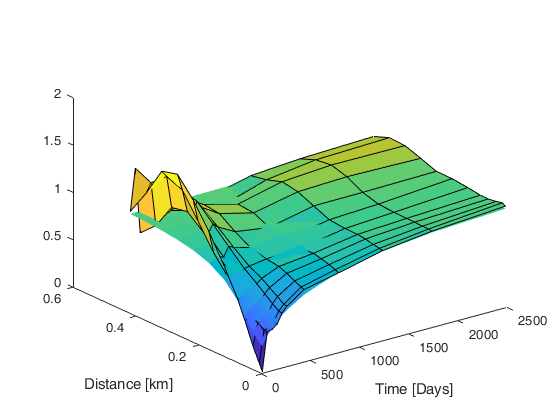

id=1:numel(Dval);
rmse = @(x) nanmean( ( Gneiting_fit(x,id)  -  Dval(id).^2./2).^2 );
covr=fminsearch(rmse,mean(solX),optimset('PlotFcn',@optimplotfval));
sprintf('%.2f ',covr)

Figure

COV=covr(1)+covr(2)-covr(2).*Gneiting(X(:), Y(:), covr(3), covr(4), covr(5), covr(6), covr(7));
COV=reshape(COV,size(X,1),size(X,2));
figure; hold on;
s=surf(X,Y,COV);
surf(X,Y,M');  ylabel('Distance [km]'); xlabel('Time [Days]');
s.EdgeColor='none'; view(3)
% id=randi(numel(Dval),500000,1);
% scatter3(Dist_km(id),Dtime(id),Dval(id).^2,'.k');


## 4.5 Kriging residual

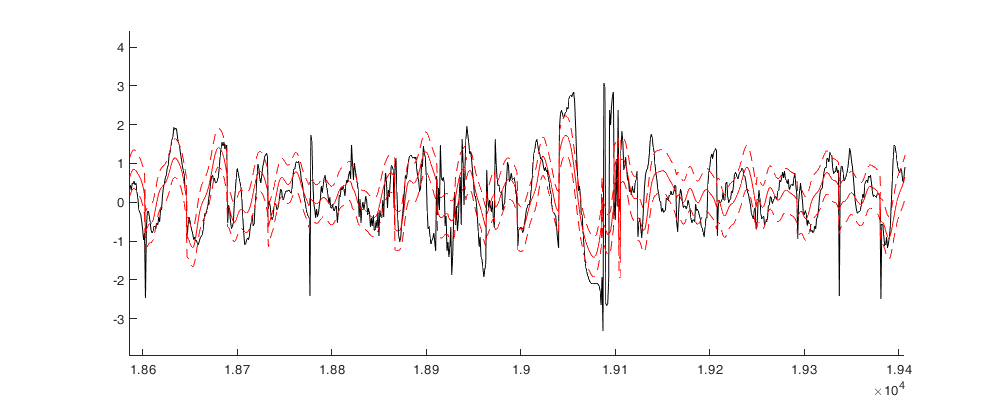

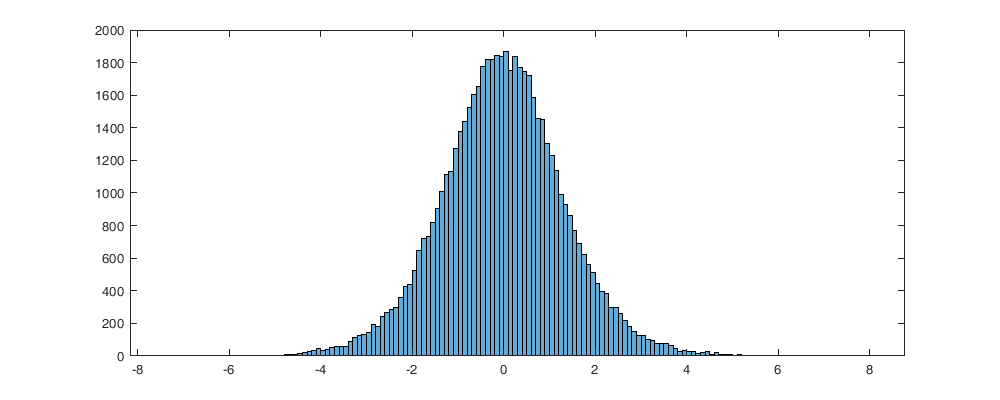

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
covr = [0.20 0.87 548.24 0.09 1.00 0.38 1.00];

z=data.resnorm;

Cr = covr(2).*Gneiting(Dist_km, Dtime, covr(3), covr(4), covr(5), covr(6), covr(7));
Cr = sparse(Did,Dnid,Cr);
Cr = Cr + spdiags(repmat(covr(1)+covr(2),size(Cr,1),1),0,size(Cr,1),size(Cr,2));

z_est=nan(size(z));
z_sigma=nan(size(z));

parfor i_data=1:height(data)
    
    neigh = Dnid(Did==i_data);
    neigh(data.dateradar(neigh)==data.dateradar(i_data))=[];
 
    Cab = full(Cr(neigh,i_data));
    neigh=neigh(Cab>.1);

    Caa = full(Cr(neigh,neigh));
    Cab = full(Cr(neigh,i_data));

    % Simple
    lambda = Caa \ Cab;
    z_est(i_data) =  lambda' * z(neigh);
    z_sigma(i_data) = covr(1) + covr(2) - lambda' * Cab;
    
    % Ordinary
%     lambda = [Caa ones(size(Caa,1),1); ones(1,size(Caa,1)) 0] \ [ Cab ; 1];
%     z_est(i_data) =  lambda(1:end-1)' * z(neigh);
%     z_sigma(i_data) = cov(1) + cov(2) - lambda(1:end-1)' * Cab - lambda(end);
    
%        figure; hold on;
%        scatter3(data.lon(i_data),data.lat(i_data),data.time(i_data),'r','filled')
%       % scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],Cab,'filled')
%       scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],lambda,'filled')
end

Figure

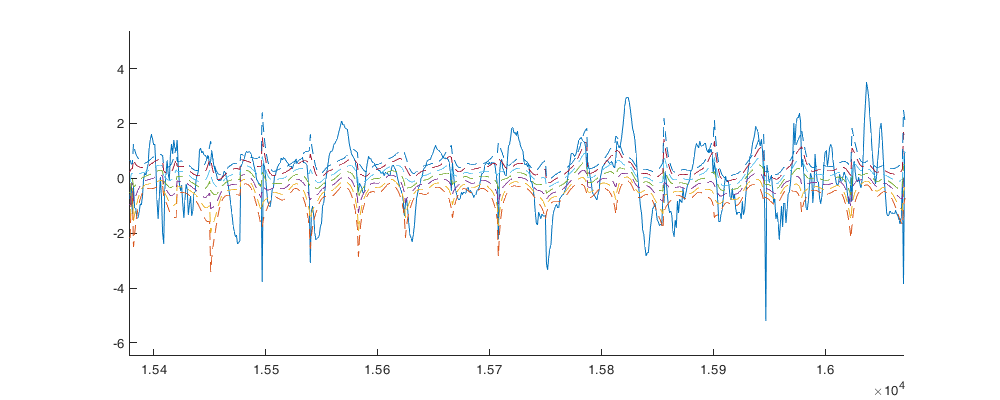

 figure('position',[0 0 1000 400]); hold on;
plot(z,'k');
plot(z_est,'r')
plot(z_est-z_sigma,'--r')
plot(z_est+z_sigma,'--r')
err_norm = (z_est-z)./(z_sigma);

 figure('position',[0 0 1000 400]); histogram( err_norm );

## 4.6 Back Normalized

data.resest = NscoreRes.inverse(bsxfun(@times,sqrt(polyval(pr,data.scoret)),bsxfun(@plus , z_est, z_sigma*(-3:3))));
figure('position',[0 0 1000 400]); hold on;
plot(data.res)
plot(data.resest,'--')

## 5. Assemble the estimation

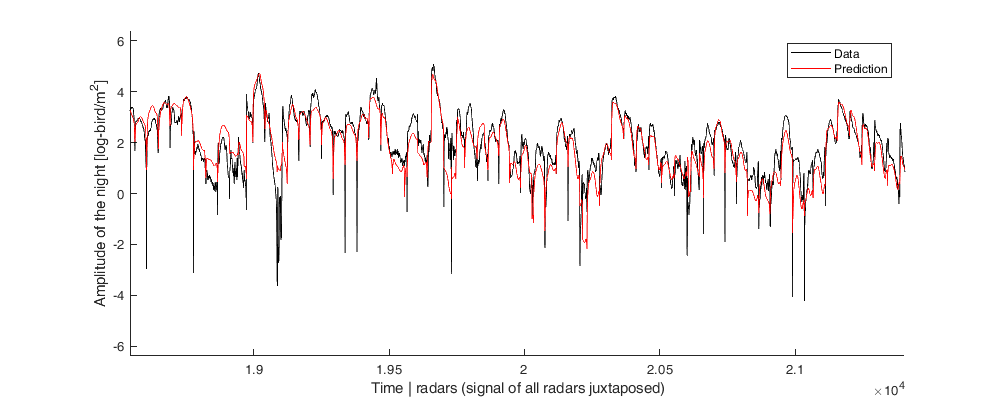

data.logdens_est = pred([pf(:); Aest(:)],size(Aest),nb_poly,data.scoret,data.dateradar)+data.resest(:,4);

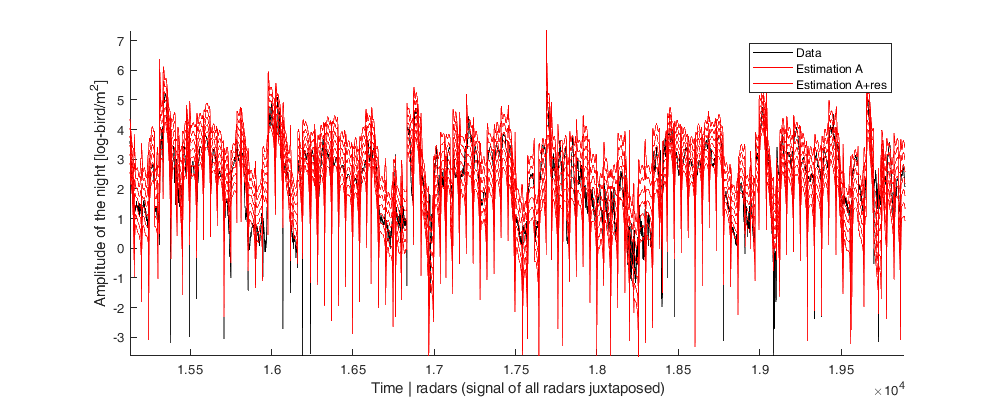

data.dens_est = exp(data.logdens_est);

figure('position',[0 0 1000 400]); hold on;
plot(data.logdens,'k');
plot(pred([pf(:); Aest(:)],size(Aest),nb_poly,data.scoret,data.dateradar),'b')
plot(data.logdens_est,'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Estimation A','Estimation A+res')
for i=-3:3

    data.logdens_est_err(:,i+4) = pred([pf(:); reshape(Aest_err(:,:,i+4),numel(Aest),1)],size(Aest),nb_poly,data.scoret,data.dateradar)+data.resest(:,i+4);
end

figure('position',[0 0 1000 400]); hold on;
plot(data.logdens,'k');
plot(data.logdens_est_err,'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Estimation A','Estimation A+res')

## 6. Map prediction

## 6.1 Initialization of the grid

g.lat=43:68;
g.lon=-5:30;
g.time = start_date-1:1/24/4:end_date-1;
[g.LAT,g.LON,g.TIME]=ndgrid(g.lat,g.lon,g.time);


Mask water

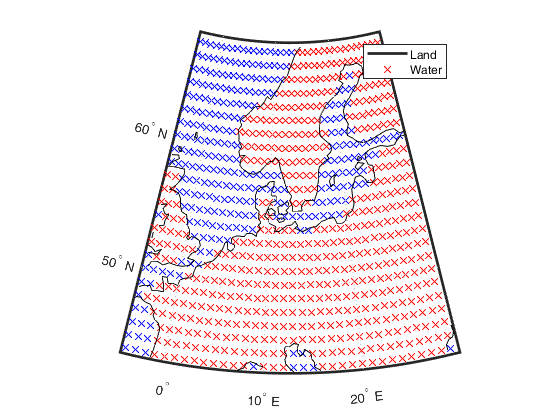

g.lat_grid = g.LAT(:,:,1); g.lon_grid = g.LON(:,:,1);

% coast = load('coast.mat');
% [Z, R] = vec2mtx(coast.lat, coast.long,1, [-90 90], [-90 270], 'filled');
% g.mask_water = ltln2val(Z, R, g.lat_grid, g.lon_grid);
% figure; worldmap(Z, R); geoshow(Z, R, 'DisplayType', 'texturemap')
% colormap([0 1 0;0 0 0;0 1 0;0 0 1])
% plotm(g.lat_grid(g.mask_water==0),g.lon_grid(g.mask_water==0),'or')
% plotm(g.lat_grid(g.mask_water==1),g.lon_grid(g.mask_water==1),'ob')
% plotm(g.lat_grid(g.mask_water==2),g.lon_grid(g.mask_water==2),'og')

addpath('C:\Users\rafnu\Documents\MATLAB\landmask\landmask')
g.mask_water = landmask(g.lat_grid,g.lon_grid);


load coastlines; figure; hold on; 
worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(g.lat_grid(g.mask_water),g.lon_grid(g.mask_water),'xr')
plotm(g.lat_grid(~g.mask_water),g.lon_grid(~g.mask_water),'xb')
plotm(coastlat, coastlon,'k')
legend({'Land','Water'})

Sunrise and sunset

load('./data/sunrisesunset_grid.mat')
tim_d2=datestr(tim_d,'yyyy-mmm-dd');
sunrs_b = string(datetime(sunrs_b,'convertfrom','datenum'),'HH:mm:ss');
sunrs_e = string(datetime(sunrs_e,'convertfrom','datenum'),'HH:mm:ss');
g.sunrise = strings(size(g.LAT));
g.sunset = strings(size(g.LAT));
for i_t=2:numel(tim_d)
    id = g.time>tim_d(i_t)-1 & g.time<=tim_d(i_t);
    for i_lat=1:numel(lat_d)
        for i_lon=1:numel(lon_d)
            g.sunset(i_lat,i_lon,id) = join([tim_d2(i_t-1,:), sunrs_e(i_lat,i_lon,i_t-1)])   ; % sunrs_e(i_lat,i_lon,i_t-1)
            g.sunrise(i_lat,i_lon,id) = join([tim_d2(i_t,:), sunrs_b(i_lat,i_lon,i_t)]); % sunrs_b(i_lat,i_lon,i_t)
        end
    end
end
g.sunset = datetime(g.sunset);
g.sunrise = datetime(g.sunrise);

figure

figure; hold on;
plot(g.time(:),reshape(mean(mean(g.sunset,1),2),1,2017))
plot(g.time(:),reshape(mean(mean(g.sunrise,1),2),1,2017))
legend('sunset','sunrise')

Score time of night

g.scoret = datenum(g.TIME-mean(cat(4,g.sunrise,g.sunset),4)) ./ datenum(g.sunrise-g.sunset)*2;

h=figure(2); load coastlines; 
F2(numel(g.time)-1) = struct('cdata',[],'colormap',[]); 
for i_t = 1:numel(g.time)-1
    clf; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,g.scoret(:,:,i_t))
    plotm(coastlat, coastlon,'k')
    title(datestr(g.time(i_t))); caxis([-1 1]); drawnow;
    F2(i_t) = getframe(h);
end
v=VideoWriter('scoret.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);

figure;
plot(g.TIM(:), g.scoret(:), '.k' )

Mask of the day

g.mask_day =  g.scoret<-1 | g.scoret>1;

[~,g.dateradar] = ismember(round(datenum(reshape(g.sunrise(1,1,:),numel(g.time),1))),uniqueDate);
g.dateradar(g.dateradar==0)=1;

## 6.2 Amplitude Kriging

Initialized hard data (radar) without the nan value.

z=Af_norm(~isnan(Af_norm(:)));

Built covariance of the radar data

XY = [repmat([dc.lat]', numel(uniqueDate),1) repmat([dc.lon]', numel(uniqueDate),1)];
T = repelem(uniqueDate',numel(dc),1);
Dist_km = pdist(XY,@lldistkm);
Dtime = pdist(T);

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
cova = [0.03 0.97 836 2.4 0.54 0.77 0];

Ca = cova(2).*Gneiting(squareform(Dist_km),squareform(Dtime), cova(3), cova(4), cova(5), cova(6), cova(7));
Ca = Ca + diag(repmat(cova(1),size(Ca,1),1));

Remove the nan value

XY(isnan(Af_norm(:)),:)=[];
T(isnan(Af_norm(:)))=[];
Ca(isnan(Af_norm(:)),:)=[];
Ca(:,isnan(Af_norm(:)))=[];

Initialized the simulated grid

g.alat=g.lat; g.alon=g.lon; g.atime=uniqueDate;
[g.aLAT,g.aLON,g.aTIME]=ndgrid(g.alat,g.alon,g.atime);

Za_est=nan(size(g.aLAT));
Za_sigma=Za_est;

Perform the kriging

% 10min
for i_d=1:numel(Za_est)
    %if g.mask_water(i_d)
        Dist_km_mp = lldistkm([g.aLAT(i_d) g.aLON(i_d)], XY );
        Dtime_mp = abs(g.aTIME(i_d)-T);

        Cab = cova(2).*Gneiting(Dist_km_mp,Dtime_mp, cova(3), cova(4), cova(5), cova(6), cova(7));

        lambda = Ca  \  Cab;
        Za_est(i_d) =  lambda' * z;
        Za_sigma(i_d) = cova(1) + cova(2) - lambda' * Cab;
    %end
end

Figure

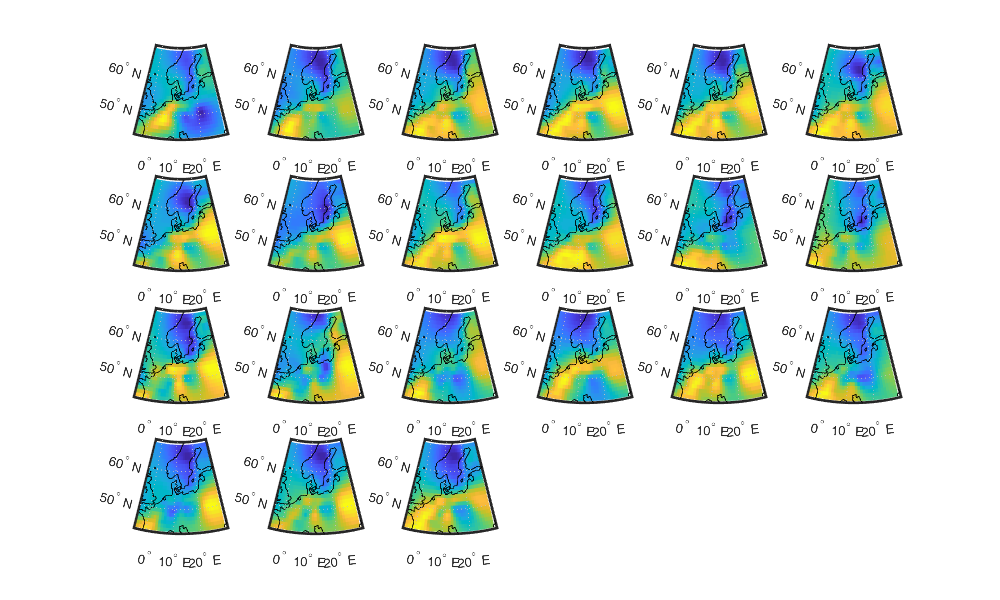

figure('position',[0 0 1000 600]); load coastlines;

for i_t = 1:numel(g.atime)-1
    subplot(4,6,i_t); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,Za_est(:,:,i_t))
    %scatterm([dc.lat],[dc.lon],[],Af_norm(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
end

Video

h=figure(2); load coastlines; 
F2(numel(g.atime)-1) = struct('cdata',[],'colormap',[]); 
for i_t = 1:numel(g.atime)-1
    clf; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,Za_est(:,:,i_t))
    scatterm([dc.lat],[dc.lon],[],Af_norm(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
    title(datestr(g.atime(i_t))); caxis([-1 1]); drawnow;
    F2(i_t) = getframe(h);
end
v=VideoWriter('AmplitudeGrid.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);

## 3.5 Back-transform

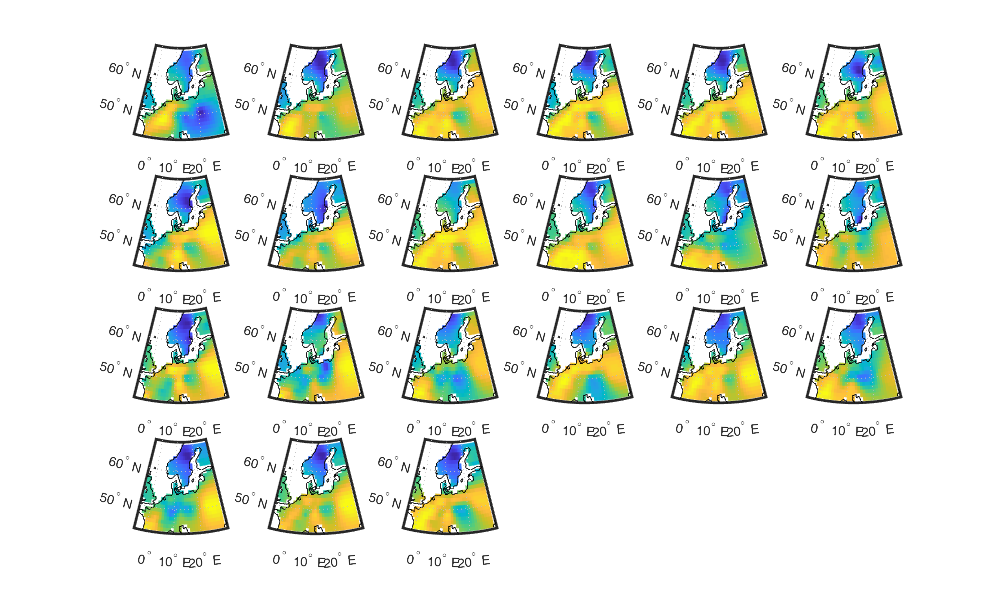

g.Aest = NscoreA.inverse(Za_est);
g.Aest(~repmat(g.mask_water,1,1,size(Za_est,3)))=nan;
for i=-3:3
    g.Aest_err(:,:,:,i+4) = NscoreA.inverse(Za_est+Za_sigma.*i);
end

figure('position',[0 0 1000 600]); load coastlines;

for i_t = 1:numel(g.atime)-1
    subplot(4,6,i_t); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);
    surfm(g.lat_grid,g.lon_grid,g.Aest(:,:,i_t))
    %scatterm([dc.lat],[dc.lon],[],Af_norm(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
end

## 6.3 Residu Kriging

time_max=0.45;
Ddist_dc_km = squareform(pdist([[dc.lat]' [dc.lon]'],@lldistkm));

nid1=nan(height(data),1);
for i_data=1:height(data)
    nid1(i_data)=sum(abs(data.time(i_data)-data.time)<=time_max);
end

n_neigh = max(nid1);
Ddist_km = nan(n_neigh, height(data));
Dtime = nan(n_neigh, height(data));
Did = nan(n_neigh, height(data));
Dnid = nan(n_neigh, height(data));

for i_data=1:height(data)
    c=abs(data.time(i_data)-data.time);
    id1=find(c<=time_max);
    Ddist_km(:,i_data) = [Ddist_dc_km(data.i_d(i_data),data.i_d(id1)) nan(1,n_neigh-nid1(i_data))];
    Dtime(:,i_data) = [c(id1) ; nan(n_neigh-nid1(i_data),1)];
    Did(:,i_data) = [i_data*ones(numel(id1),1) ; nan(n_neigh-nid1(i_data),1)];
    Dnid(:,i_data) = [id1 ; nan(n_neigh-nid1(i_data),1)];
end

Ddist_km=Ddist_km(~isnan(Ddist_km));
Dtime=Dtime(~isnan(Dtime));
Did=Did(~isnan(Did));
Dnid=Dnid(~isnan(Dnid));


Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
covr = [0.20 0.87 548.24 0.09 1.00 0.38 1.00];

Cr = covr(2).*Gneiting(Ddist_km, Dtime, covr(3), covr(4), covr(5), covr(6), covr(7));
Cr = sparse(Did,Dnid,Cr);
Cr = Cr + spdiags(repmat(covr(1)+covr(2),size(Cr,1),1),0,size(Cr,1),size(Cr,2));

z=data.resnorm;
z_est=nan(size(g.LAT));
z_sigma=z_est;

% parpool(24)

for i_t=1:numel(g.time)
    Dtime_mp = abs(datenum(g.time(i_t))-data.time);
    neigh =  Dtime_mp < time_max;
    
    Caa = full(Cr(neigh,neigh));
    
    z_est_tmp=nan(size(z_est(:,:,i_t)));
    z_sigma_tmp=nan(size(z_est(:,:,i_t)));
    
    parfor i_d=1:numel(z_est(:,:,i_t))
        Dist_km_mp = lldistkm([g.lat_grid(i_d) g.lon_grid(i_d)], [data.lat(neigh) data.lon(neigh)] );

        Cab = covr(2).*Gneiting(Dist_km_mp, Dtime_mp(neigh), covr(3), covr(4), covr(5), covr(6), covr(7));

        % Simple
        lambda = Caa \ Cab;
        z_est_tmp(i_d) =  lambda' * z(neigh);
        z_sigma_tmp(i_d) = covr(1) + covr(2) - lambda' * Cab;

        % Ordinary
    %     lambda = [Caa ones(size(Caa,1),1); ones(1,size(Caa,1)) 0] \ [ Cab ; 1];
    %     z_est(i_data) =  lambda(1:end-1)' * z(neigh);
    %     z_sigma(i_data) = cov(1) + cov(2) - lambda(1:end-1)' * Cab - lambda(end);

    %        figure; hold on;
    %        scatter3(data.lon(i_data),data.lat(i_data),data.time(i_data),'r','filled')
    %       % scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],Cab,'filled')
    %       scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],lambda,'filled')
    end
    z_est(:,:,i_t) = z_est_tmp;
    z_sigma(:,:,i_t) = z_sigma_tmp;
end

z_est(g.mask_day)=nan;
z_est(~repmat(g.mask_water,1,1,size(z_est,3)))=nan;

FIgure

h=figure(2); load coastlines; 
F2(numel(g.time)-1) = struct('cdata',[],'colormap',[]); 
for i_t = 1:size(z_est,3)
    clf; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,z_est(:,:,i_t))
    % scatterm([dc.lat],[dc.lon],[],Af_norm(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
    colorbar; caxis([-1 1])
    title(datestr(g.time(i_t))); caxis([-1 1]); drawnow;
    F2(i_t) = getframe(h);
end
v=VideoWriter('ResidusGrid.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);

Back-transform

std_scoret = polyval(pr,g.scoret);
std_scoret(g.scoret<-1 | g.scoret>1)=nan;
g.ResEst = NscoreRes.inverse(sqrt(std_scoret).*z_est);
% g.ResEst = NscoreRes.inverse(bsxfun(@times,sqrt(polyval(pr,g.scoret)),bsxfun(@plus , z_est, z_sigma*(-3:3))));

Figure

h=figure(2); load coastlines; 
F2(numel(g.time)-1) = struct('cdata',[],'colormap',[]); 
mask_fullday = find(~reshape(all(all(isnan(g.ResEst),1),2),numel(g.time),1));
for i_t = 1:numel(mask_fullday)
    clf; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,g.ResEst(:,:,mask_fullday(i_t)))
    % scatterm([dc.lat],[dc.lon],[],Af_norm(:,i_t),'filled','MarkerEdgeColor','k')
    plotm(coastlat, coastlon,'k')
    title(datestr(g.time(mask_fullday(i_t)))); caxis([-1 1]); drawnow;
    F2(i_t) = getframe(h);
    colormap
end
v=VideoWriter('ResidusGrid.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);

## 6.4 Reassemble

g.logdens = polyval(pf,g.scoret) + g.Aest(:,:,g.dateradar) + g.ResEst;
g.dens = exp(g.logdens);

Figure

h=figure(2); load coastlines; 
mask_fullday = find(~reshape(all(all(isnan(g.ResEst),1),2),numel(g.time),1));
F2(numel(mask_fullday)) = struct('cdata',[],'colormap',[]); 
for i_t = 1:numel(mask_fullday)
    clf; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
    surfm(g.lat_grid,g.lon_grid,g.logdens(:,:,mask_fullday(i_t)))

    gtit = datenum(g.time(mask_fullday(i_t)+([-1 0 1])));
    id = mean(gtit(1:2))<data.time & mean(gtit(2:3))>data.time;
    scatterm(data.lat(id),data.lon(id),[],data.logdens(id),'filled','MarkerEdgeColor','k')
    
    plotm(coastlat, coastlon,'k')
    title(datestr(g.time(mask_fullday(i_t)))); caxis([-4 4]); drawnow;
    F2(i_t) = getframe(h);
end

v=VideoWriter('AmplitudeResidusGrid.avi');
v.FrameRate = 4;  % Default 30
v.Quality = 75;
open(v);
writeVideo(v, F2);
close(v);

Save

save('krigingAmplitudeResidus_grid','g','z_est','Za_est','Za_sigma')